# Praktikum 4 - Shift 2 Kamis

`14 Oktober 2021`

`Nama : ``Asisten Praktikum`

`NIM  :`

## Nomor 1

Tuliskan kelebihan polinom interpolasi Lagrange dibandingkan polinom interpolasi Newton !

#### **Jawaban :**

Polinom interpolasi Lagrange lebih mudah untuk diprogram, karena polinom ini tidak memerlukan komputasi dan penyimpanan tabel beda terbagi. Bentuk polinom Lagrange lebih mudah digunakan apabila orde polinom yang diperlukan sudah diketahui sebelumnya.

## **Nomor 2**

Bangunlah suatu fungsi `polinom_lagrange.m` yang menerima input array $X=[x_0, x_1, x_2, ..., x_n]$ dan $Y=[y_0, y_1, y_2, ..., y_n]$ dimana $f(x_i)=y_i$ untuk $1\leq i\leq n$, yang menghasilkan keluaran $p_n(x)$, polinom interpolasi Lagrange orde $n$ yang melalui semua titik $((x_0, f(x_0)), (x_1, f(x_1)), ..., (x_n, f(x_n))$.

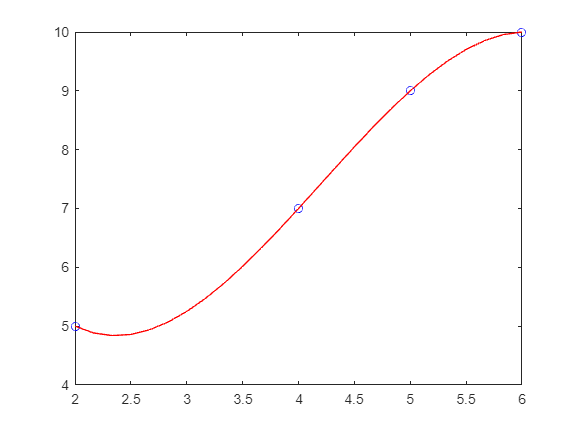

% Run section ini untuk memeriksa jawaban anda!
X = [2,4,5,6];
Y = [5,7,9,10];
X1 = linspace(2,6,25);
f = polinom_lagrange(X,Y);
plot(X,Y,'bo', X1, f(X1), 'r-')

## Nomor 3

Pada tahun 2420, Ilmuwan bernama Profesor Charles Xavier menemukan mesin waktu. Karena bosan, kamu pergi ke tahun 2550 SM di Mesir Kuno. 

Kamu menemui orang - orang yang sedang bekerja membangun piramida. Mereka sedang mencoba menghitung nilai dari fungsi $\ln(x)$ di interval $[1,11]$. Tetapi, masyarakat Mesir Kuno tentunya tidak punya kalkulator Casio.

Mereka hanya tahu nilai dari fungsi $\ln(x)$ untuk beberapa nilai $x$ saja, yaitu $x\in \{1,4,5,7,11\}$sebagai berikut

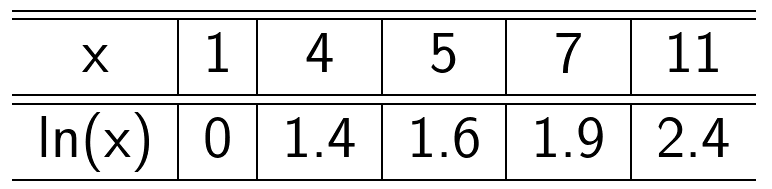

Tanpa kalkulator, tentunya menghitung polinomial akan jauh lebih mudah daripada menghitung $\ln(x)$ secara langsung.

### 3A

Bantu masyarakat Mesir Kuno untuk menghampiri nilai $\ln(x)$ di seluruh interval $[1,11]$ dengan membangun suatu polinomial Interpolasi Lagrange orde $4$ $p_4(x)$menggunakan informasi pada tabel diatas!

% Lengkapi kode dibawah ini !
x = [1,4,5,7,11];
ln_x = [0, 1.4, 1.6, 1.9, 2.4];
p4 = polinom_lagrange(x, ln_x);

### 3B

Plot polinom Interpolasi Lagrange yang kamu peroleh di nomor 3A untuk $x\in [1,11]$ bersama dengan plot $f(x)=\ln(x)$.

Apa yang kamu dapat simpulkan dari grafik tersebut? Apakah hampiran ini sudah baik?

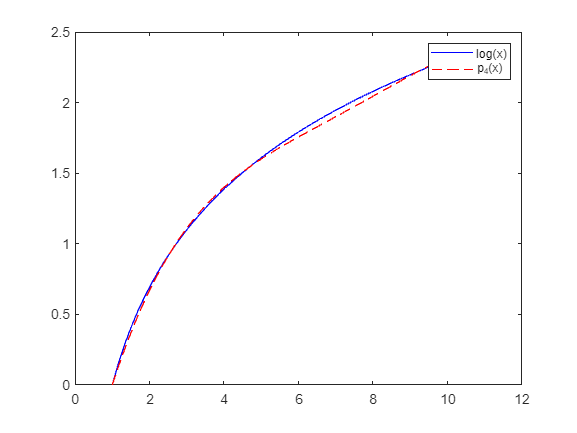

X = linspace(1, 11, 60);
f = @(x) log(x);
plot(X, f(X), 'b-', X, p4(X), 'r--')
legend('log(x)', 'p_4(x)')